clear all; close all
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.2616e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   1.2616e-13



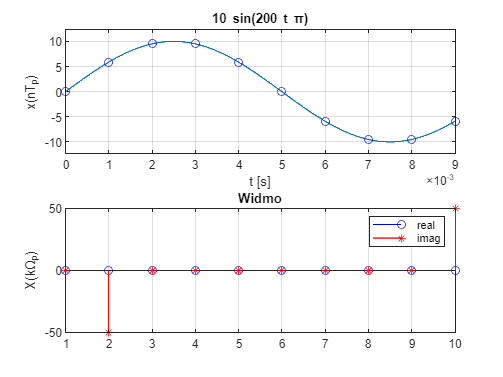

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
stem(real(Xk),'ob'); grid on, hold on
stem(imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

clear all; close all
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.2616e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   1.2616e-13



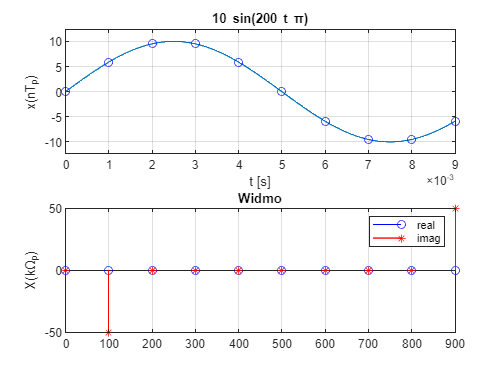

figure;
subplot(2,1,1)


ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)

%poprawki
wk = fp*[0:N-1]/N;
stem(wk, real(Xk), 'ob'); grid on; hold on;
stem(wk, imag(Xk), '*r');


title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

clear all; close all
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1i*2*pi*k*n/N);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.2341e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   1.2341e-13



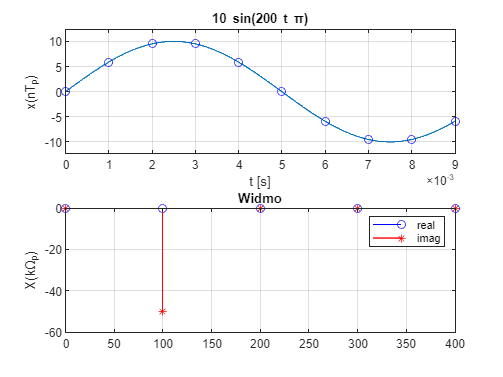

figure;
subplot(2,1,1)


ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)

%poprawki
wk = fp*[0:N/2-1]/N; % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');


title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

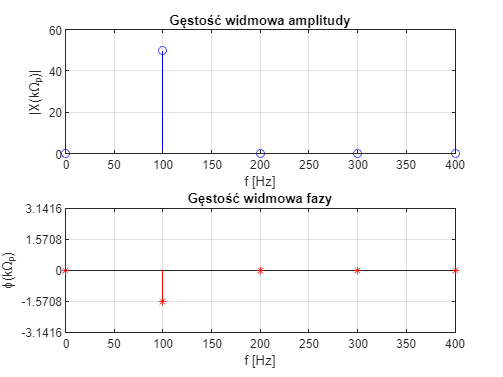


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

clear all; close all
syms t w
N = 15; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1i*2*pi*k*n/N);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 5.1371e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   5.1371e-13



figure;
subplot(2,1,1)


ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)

%poprawki
wk = fp*[0:N/2-1]/N; % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;

stem(wk, imag(Xk(1:N/2)), '*r');

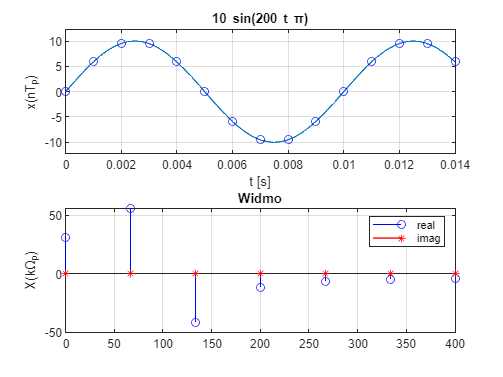



title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;

ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;

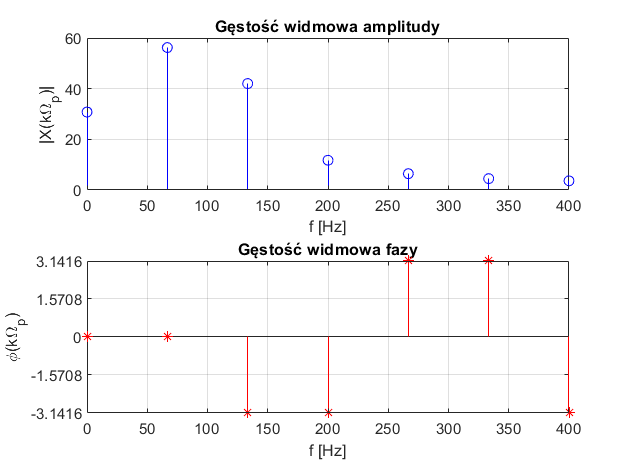

yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

clear all; close all
syms t w
N = 20; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1i*2*pi*k*n/N);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.4883e-12

disp('DFT error:'); disp(dft_err);

DFT error:
   1.4883e-12



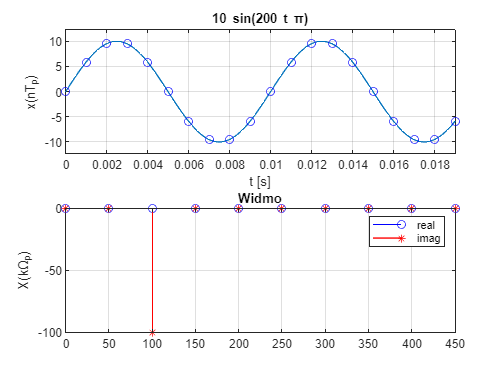

figure;
subplot(2,1,1)


ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)

%poprawki
wk = fp*[0:N/2-1]/N; % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');


title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

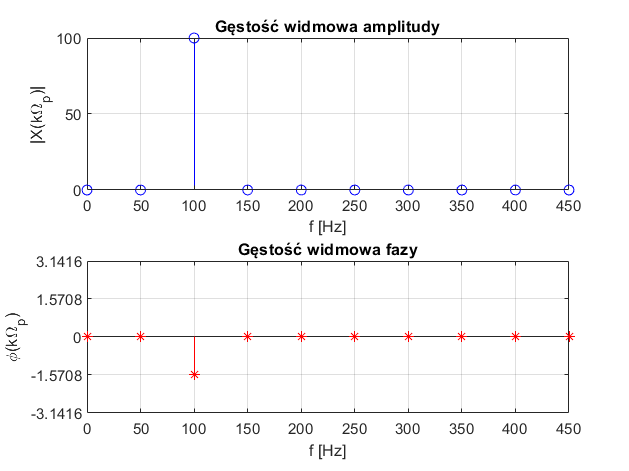


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

clear all; close all
syms t w
N = 20; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f3 = 150; %Hz
x1 =A1*sin(2*pi*f3*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1i*2*pi*k*n/N);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.1183e-12

disp('DFT error:'); disp(dft_err);

DFT error:
   1.1183e-12



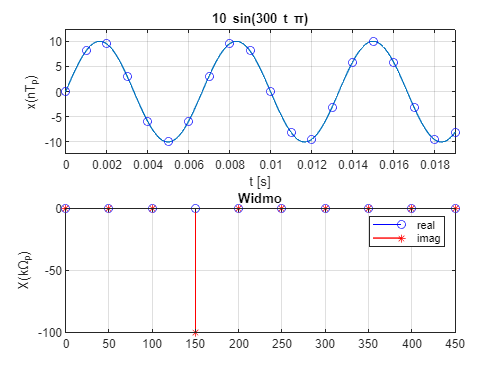

figure;
subplot(2,1,1)


ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)

%poprawki
wk = fp*[0:N/2-1]/N; % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');


title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

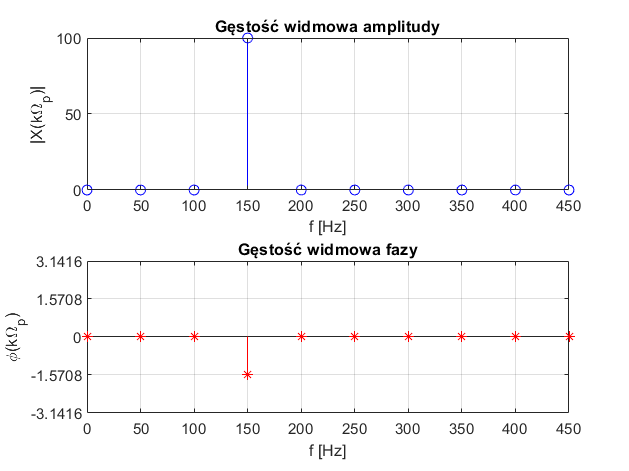


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

% okno trojkatne

clear all; close all
syms t w
N = 20; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f3 = 150; %Hz
x1 =A1*sin(2*pi*f3*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
xn = xn.*triang(N)';
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1i*2*pi*k*n/N);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 6.4001e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   6.4001e-13



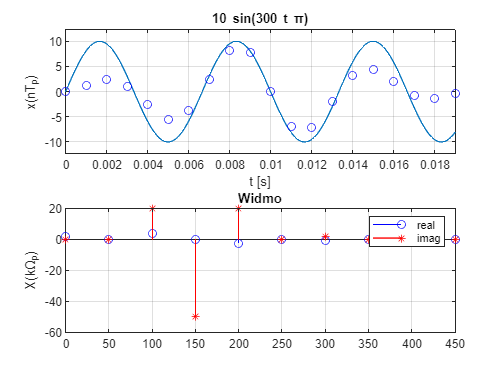

figure;
subplot(2,1,1)


ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)

%poprawki
wk = fp*[0:N/2-1]/N; % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');


title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

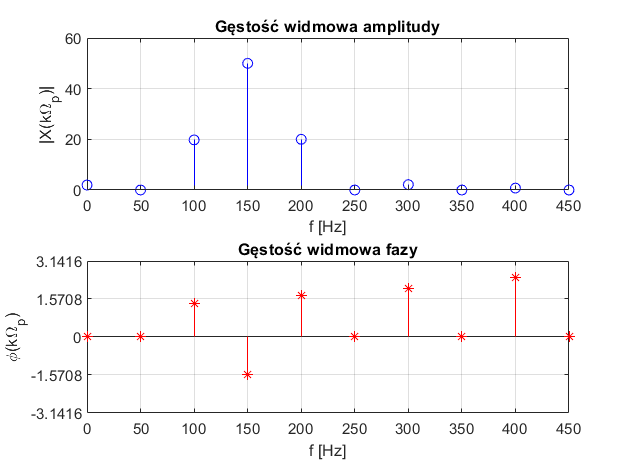


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

%okno gaussa

clear all; close all
syms t w
N = 20; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f3 = 150; %Hz
x1 =A1*sin(2*pi*f3*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
xn = xn.*window(@gausswin,N,2.5)';
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1i*2*pi*k*n/N);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 7.1807e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   7.1807e-13



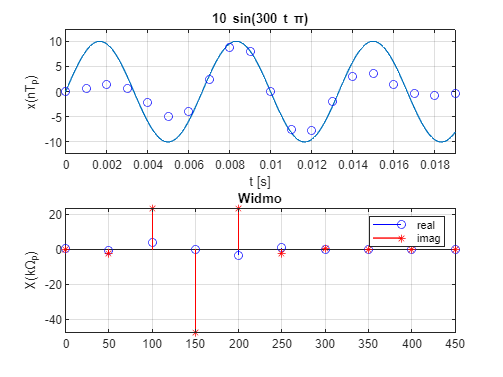

figure;
subplot(2,1,1)


ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)

%poprawki
wk = fp*[0:N/2-1]/N; % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');


title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

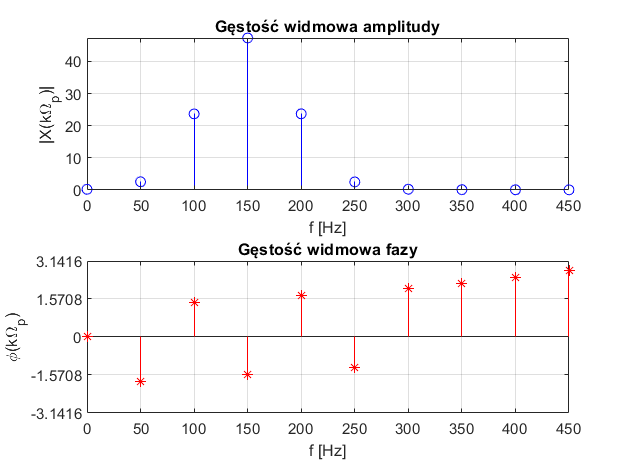


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

% okno czebyszewa
clear all; close all
syms t w
N = 20; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f3 = 150; %Hz
x1 =A1*sin(2*pi*f3*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
xn = xn.*chebwin(N)';
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1i*2*pi*k*n/N);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 7.0485e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   7.0485e-13



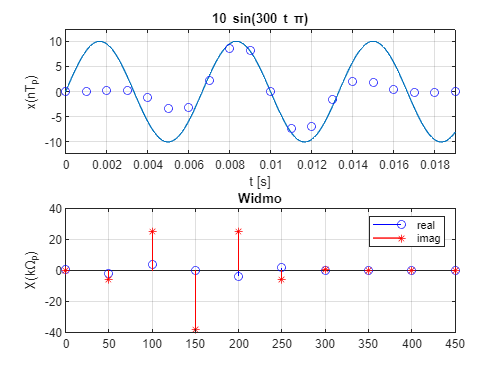

figure;
subplot(2,1,1)


ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)

%poprawki
wk = fp*[0:N/2-1]/N; % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');


title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

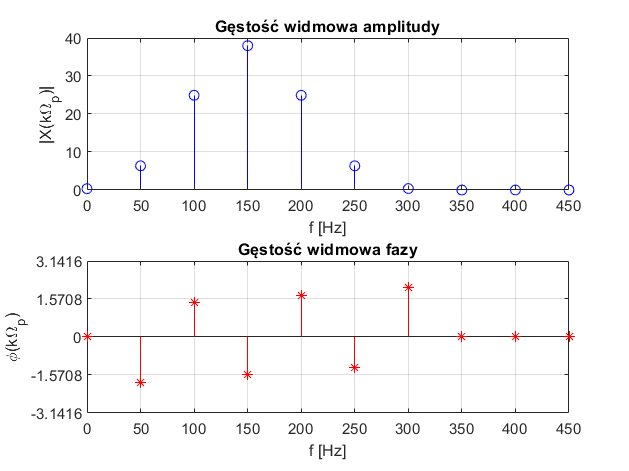


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

clear all; close all
syms t w
N = 20; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; 
f1 = 100; %Hz
f2 = 200;
A2 = 5.0;
x1 = A1*sin(2*pi*f1*t) + A2*sin(2*pi*f2*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));

%przesuniecie cykliczne
xm = zeros(1,N);
m = 2;
for n = 0:N-1
 xm(n+1) = xn(mod(n + m, N)+1);
end
xn = xm;

Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1i*2*pi*k*n/N);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.5463e-12

disp('DFT error:'); disp(dft_err);

DFT error:
   1.5463e-12



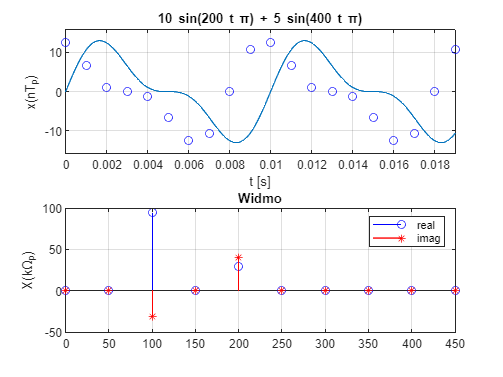

figure;
subplot(2,1,1)


ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)

%poprawki
wk = fp*[0:N/2-1]/N; % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');


title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

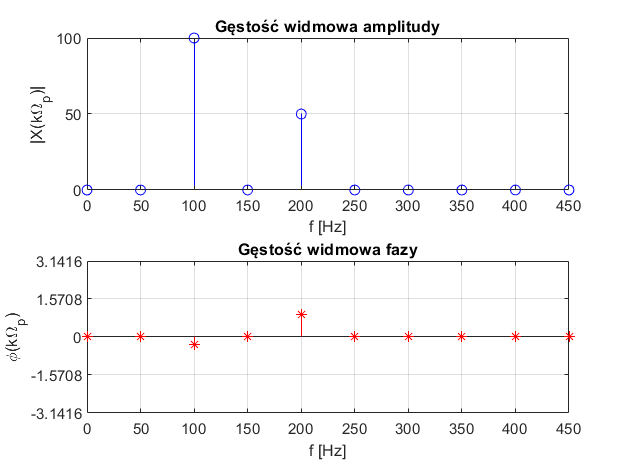


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

%Zadanie domowe
clear all; close all
syms t w



N = 15; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));

W = dftmtx(N);
Xk = xn*W;

Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 3.7752e-14

disp('DFT error:'); disp(dft_err);

DFT error:
   3.7752e-14



figure;
subplot(2,1,1)


ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)

%poprawki
wk = fp*[0:N/2-1]/N; % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;

stem(wk, imag(Xk(1:N/2)), '*r');



title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;

ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;

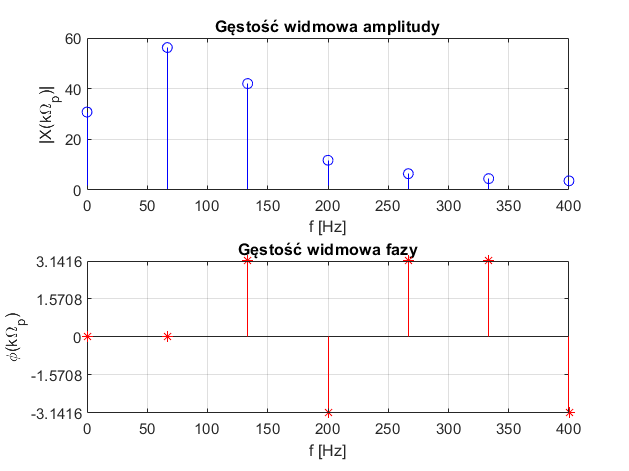

yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');